clear
%clearvars

raw(1) = load('Moving.mat');
raw(2) = load('Powerful.mat');
raw(3) = load('Melodic.mat');
raw(4) = load('Precise.mat');
raw(5) = load('Slow.mat');
raw(6) = load('bouncy.mat');
raw(7) = load('Walter.mat');

for i = 1:length(raw)
    minutes = raw(i).Acceleration.Timestamp.Minute;
    seconds = raw(i).Acceleration.Timestamp.Second;
    time = minutes*60 + seconds;
    disp = sqrt(raw(i).Acceleration.X.^2 + raw(i).Acceleration.Y.^2 + raw(i).Acceleration.Z.^2);
    
    Data(i).time = time - time(1);
    
    Data(i).X = disp;
end

Fs = 8000

Fs = 8000

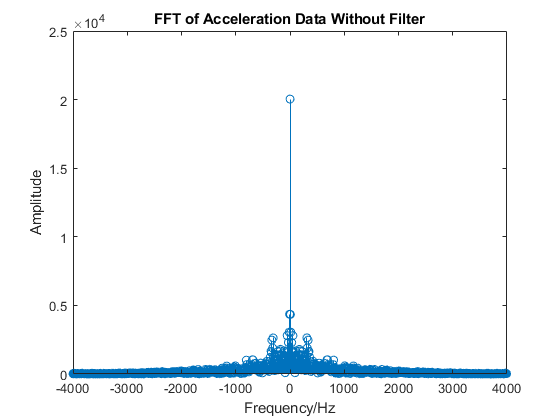

freq_fft = generate_fft(disp);
shifted_freq_radpersample = freq_fft(1,:);
shifted_freq_radpersecond = shifted_freq_radpersample*Fs;
shifted_freq_hz = shifted_freq_radpersecond/(2*pi);
stem(shifted_freq_hz, freq_fft(2,:))
% writematrix(shifted_freq_hz', 'freq1.txt', 'Delimiter', 'tab'); 
% writematrix((freq_fft(2,:))', 'fft1.txt', 'Delimiter', 'tab'); 
shifted_freq_radpersample = freq_fft(1,:);
shifted_freq_radpersecond = shifted_freq_radpersample*Fs;
shifted_freq_hz = shifted_freq_radpersecond/(2*pi);
title('FFT of Acceleration Data Without Filter')
xlabel('Frequency/Hz')
ylabel('Amplitude')

x = high_pass_filter(disp)

x =          0   -0.2651   -0.1595    0.0136   -0.0952   -0.1322    0.0419    0.1699    0.0212   -0.1624   -0.0942   -0.0822    0.0139    0.3614    0.4953   -0.0838   -0.2125   -0.1104   -0.1556   -0.0993    0.1933   -0.0700   -0.1867   -0.1609    0.2532    0.3010   -0.0144   -0.1992    0.2771   -0.1143   -0.7237   -0.4876    0.0398    0.0290    0.5384    0.4711    0.2187   -0.5371    0.2061    0.2544   -0.5014    0.1414    0.4446    0.0043   -0.5597    0.1583   -0.3713   -0.1063   -0.0886   -0.0317


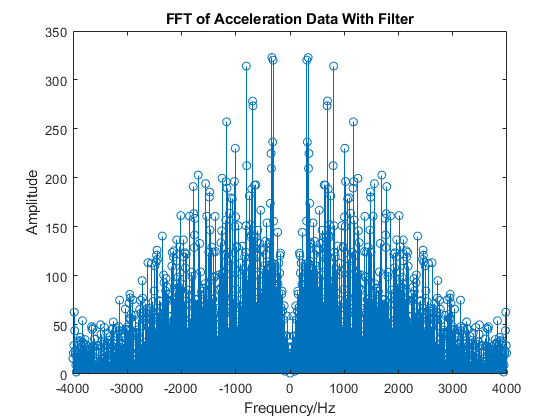

freq_fft2 = generate_fft(x');
stem(shifted_freq_hz, freq_fft2(2,:))
writematrix(shifted_freq_hz', 'freq1filter.txt', 'Delimiter', 'tab'); 
writematrix((freq_fft2(2,:))', 'fft1filter.txt', 'Delimiter', 'tab'); 
title('FFT of Acceleration Data With Filter')
xlabel('Frequency/Hz')
ylabel('Amplitude')

plot(freq_fft)

all_freqs = [130.82 138.59 146.83 155.56 164.81 174.61 185 196 207.65 220 233.08 246.94 261.63 277.18 293.66 311.13 329.63 349.23 369.99 392 415.3 440 466.16 493.88 523.25 554.37 587.33 622.25 659.26 698.46 739.99 783.99 830.61 880 932.33 987.77];    
choosing_chord_nos = data_to_chords(all_freqs,Data(1).X,Data(1).time,100)

choosing_chord_nos =     12    36     1    12    22     3    31    36    17    24


C = 10

C = 10

P = 40

P = 40

[bpm,note_length] = choosing_chord_rhythm(C)

options =      8     4     2


consistency = 10

bpm = 8

x =     0.5000    1.0000    1.5000    2.0000


t = 1

bpm = 8

note_length =     0.5000    0.5000    1.5000    1.0000    2.0000    1.0000    1.0000    0.5000


tempo = 1

tempo = 1

volume = P

volume = 40

song = []


song =

     []



for i = 1:1:length(choosing_chord_nos)
current_freq = all_freqs(choosing_chord_nos(i));
current_chord = note_to_chord_freqs(1,current_freq);
whole_wave = create_big_wave(current_chord, note_length, bpm, tempo);
adjusted_wave = (whole_wave*(volume/100))/(max(abs(whole_wave)));
song = [song adjusted_wave];
end
%sound(s,8000)
% player = audioplayer(s, 8000);
% play(player,[1 (get(player, 'SampleRate')*3)]);


sound(song,8000)


function whole_wave = create_big_wave(current_chord,note_length,bpm,tempo)
note = linspace(0,0, 8000/tempo);
for i = 1:length(current_chord)
    wave = create_sine_wave(1, current_chord(i));
    note = note + wave(1:(8000/tempo));
end
whole_wave = [];
for j = 1:1:length(note_length)
space = ((note_length(j)*2)/(bpm*2))*length(note);
note_time = length(note) - space;
whole_wave = [whole_wave note(1:note_time) zeros(1, space)];
end
end

function wave = create_sine_wave(duration, freq)
    Fs = 8000;
    Ts = 1/Fs;
    T = 0:Ts:duration;
    wave = exp(-2*T).*(sin(2*pi*freq*T)+sin(2*pi*freq/2*T));
    wave = wave(1:8000);
end

function freq_fft = generate_fft(wave)
    N = length(wave);
    frequencies_shifted = linspace(-pi, pi-2*pi/N, N) + pi/N*mod(N,2);
    fft1 = abs(fft(wave));
    final_fft = fftshift(fft1);
    freq_fft = [frequencies_shifted;final_fft'];
    
end

function y = high_pass_filter(x)
for i = 2:length(x) - 1
    y(i)=(x(i)-x(i-1))/2;
end
y(length(x)) = 0;
end

function [accel_split, time_split] = splitting_up_data(accel_data, time, step_size)
N = length(time);
num_steps = ceil(N/step_size);
for i = 1:num_steps - 1
    data_seg = [];
    time_seg = [];
    range = (step_size*(i-1)+1):(step_size*i);
    for k = 1:N
        if ismember(k, range)
            k_remapped = k - step_size*(i-1);
            data_seg(k_remapped) = accel_data(k);
            time_seg(k_remapped) = time(k);
        end
    end
    accel_split(i,:) = data_seg;
    time_split(i,:) = time_seg;
end
end

function freq1 = note_to_chord_freqs(x,note_freq)
for i = 1:1:3
    if x == 1 %major
        y = [0 4 7];
    end
    if x == 0 %minor
        y = [0 3 7];
    end        
    freq1(i) = note_freq* (2^(y(i)/12));
end
end


function [bpm,note_length] = choosing_chord_rhythm(C)
    options = [8 4 2]
    consistency = C
    
    %fround = round(frequency,1)
    for i = 1:1:length(options)
        if consistency <= (i*30)        
            bpm = options(i)
            break
        end
    end     
    x = [0.5 1 1.5 2]
    t = 1
    while t == 1
        for i  = 1:1:bpm
        pos = randi(length(x));
        note_length(i) = x(pos);
        end
        if sum(note_length) == bpm
            t = 2;
        end
    end     
end

function choosing_chord_no = data_to_chords(all_freqs,datax,datatime,stepsize)
 acc = high_pass_filter(datax);
% ask loren about step size and time thing
[accel_split, split_time] = splitting_up_data(acc, datatime, stepsize);
[rows,columns] = size(accel_split);
for i = 1:1:rows
    fft_acc(:,:,i) = generate_fft(accel_split(i,:));
end
% avg freq
[r,c,h] = size(fft_acc);
for i = 1:1:h
    avg_freq(i) = (sum(abs(fft_acc(1,:,i)).*abs(fft_acc(2,:,i))))/(c);
end
%choosing the chord
avg_freq_zero = avg_freq - min(avg_freq);
range = max(avg_freq_zero);
x= linspace(0,range,length(all_freqs));
for i = 1:1:length(avg_freq_zero)
    for j = 1:1:length(x)
        if avg_freq_zero(i) <= x(j)
            choosing_chord_no(i) = j;
            break
        end
    end
end
end